# HW5

clear 
clc

## prob 1

given a 11-point sequence $x\left(n\right)=10\cdot {\left(\ldotp 6\right)}^n$, for $n\in \left\lbrack 0,10\right\rbrack$, determine and plot ${x\left(\left(n-6\right)\right)}_{16}$.

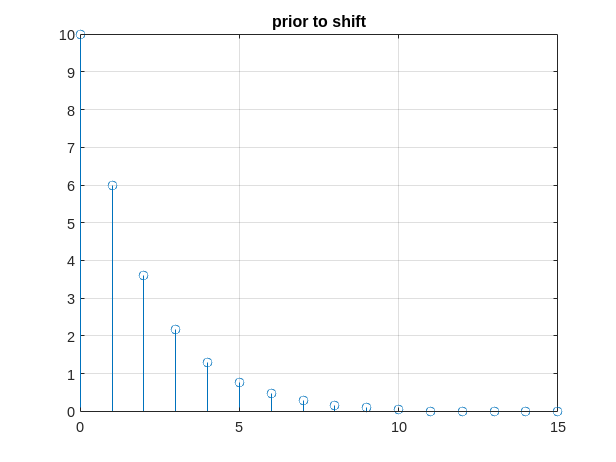

n = 0:10;
x = 10*(.6).^n;
shift = 6;
mod = 16;

append_num = 16 - length(n);

x = [x zeros(1,append_num)];
stem(0:length(x)-1,x)
title('prior to shift')
grid on

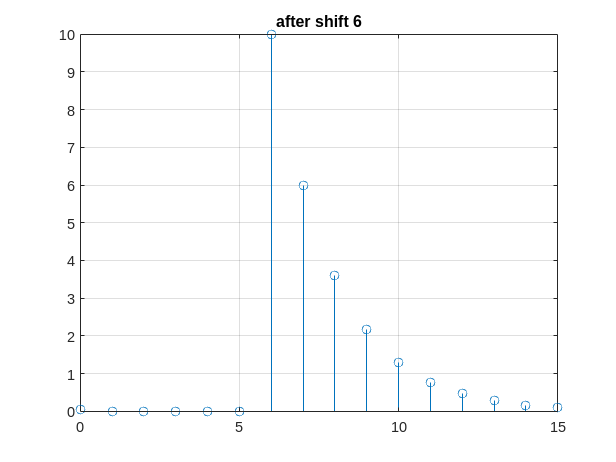


x_shift = circshift(x,shift);
stem(0:length(x)-1,x_shift)
title(sprintf('after shift %d' ,shift))
grid on

## prob 2

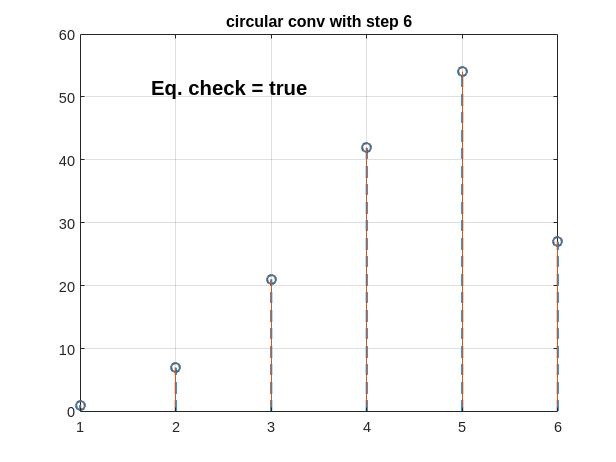

N = 6;
x_1 = [1 4 3];
x_2 = [1 3 6 9];
cconv = circConv(x_1, x_2, N);
linconv = linConv(x_1,x_2);
figure1 = figure(Name='conv comparison');
stem(1:length(cconv),cconv,LineWidth=1.4,LineStyle="--")
hold on
stem(1:length(linconv),linconv)
title(sprintf('circular conv with step %d' ,N))
grid on
hold off
if(length(cconv) == length(linconv))
    res = "true";
else 
    res = "false";
end
annotation(figure1,'textbox',...
    [0.233142857142857 0.752380952380952 0.3215 0.095714285714288],...
    'String',{sprintf('Eq. check = %s',res)},...
    'FontWeight','bold',...
    'FontSize',14,...
    'FitBoxToText','off',...
    'EdgeColor','none');

The setup only works if N = 6. we cannot have equality unless the number of elements is greater.

## prob 3 - bonus

## prob 4

A 12-point sequence is x(n) defined as $x\left(n\right)=\left\lbrace 1\;2\;4\;8\;16\;32\;32\;16\;8\;4\;2\;1\right\rbrace$

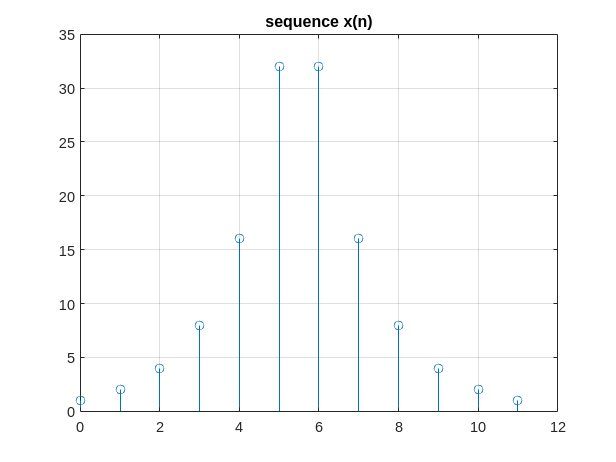

x = [1 2 4 8 16 32 32 16 8 4 2 1];
n = 0:length(x)-1;
figure
stem(n,x)
title('sequence x(n)')
grid on

N = 12

N = 12

k = n

k =      0     1     2     3     4     5     6     7     8     9    10    11


% dft

figure
X = x.*exp(-j*2*pi.*(k-1).*(n-1)./N)

X =    0.8660 - 0.5000i   2.0000 + 0.0000i   3.4641 - 2.0000i  -4.0000 - 6.9282i  -0.0000 +16.0000i -16.0000 -27.7128i  27.7128 -16.0000i  16.0000 + 0.0000i   6.9282 - 4.0000i  -2.0000 - 3.4641i  -0.0000 + 2.0000i  -0.5000 - 0.8660i


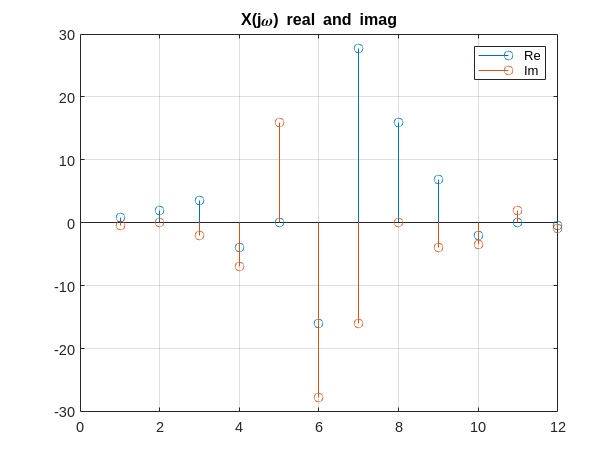

stem(1:length(X),real(X))
hold on
stem(1:length(X),imag(X))
hold off
title('X(j\omega) real and imag')
legend(["Re","Im"])
grid on

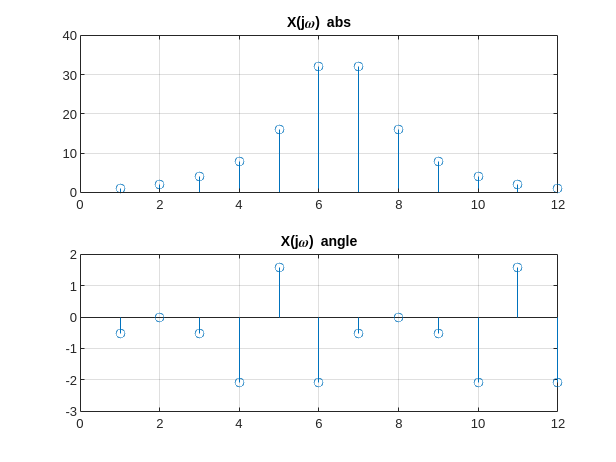

figure
subplot(2,1,1)
stem(abs(X))
title("X(j\omega) abs")
grid on
subplot(2,1,2)
stem(angle(X))
title('X(j\omega) angle')
grid on

## prob 5 - bonus


x1 = x

x1 =      1     2     4     8    16    32    32    16     8     4     2     1



figure
x = circshift(x1,randi(23));
k = 2;
p = 4;
P = [p-1 p p+1];
hold on
xshift = [circshift(x,P(1)) ;circshift(x,P(2));circshift(x,P(3))]

xshift =      2     1     1     2     4     8    16    32    32    16     8     4
     4     2     1     1     2     4     8    16    32    32    16     8
     8     4     2     1     1     2     4     8    16    32    32    16


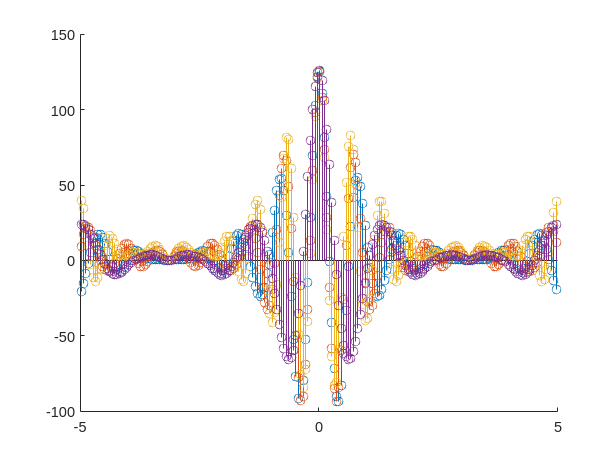

stem(-k*pi:.05:k*pi,real(dtft(xshift(1,:),-k*pi:.05:k*pi)))
stem(-k*pi:.05:k*pi,real(dtft(xshift(2,:),-k*pi:.05:k*pi)))
stem(-k*pi:.05:k*pi,real(dtft(xshift(3,:),-k*pi:.05:k*pi)))
hold on
stem(-k*pi:.05:k*pi,real(dtft(x,-k*pi:.05:k*pi)))
xlim([-5 5])
%stem(-k*pi:.05:k*pi,imag(mydtft(x,length(-k*pi:.05:k*pi))))
hold off

function [X] = dtft(x,w)
% Computes Discrete-time Fourier Transform
%   X = DTFT values computed at w frequencies
%   x = finite duration sequence over n
%   n = sample position vector
%   w = frequency location vector
for i=0:length(w)-1
    X(i+1)=0;
    for k=0:length(x)-1
        X(i+1) =X(i+1)+ exp(-1i*w(i+1)*k)* x(k+1);
    end
end
end
function y = circConv(x1, x2, N) %Circular Convolution Function

L1 = length(x1);
L2 = length(x2);

%For equation where x_3(m) = sum(from 0 to N-1) (xn)x(m-n)_moduloN equation 2.39 chapt 7
%textbook pg. 484
z1 = [x1 zeros(1, N-L1)];
z2 = [x2 zeros(1, N-L2)];
z = zeros(1,N);
    for m = 1:N
        for n = 1:N
            j = mod(m-n,N);
            j = j + 1;
            z(m) = z(m) + z1(n)*z2(j);
        end
    end

y = z;

end

function y = linConv(x1, x2) %Circular Convolution Function 

L1 = length(x1);
L2 = length(x2);

%For equation where x_3(m) = sum(from 0 to N-1) (xn)x(m-n)
z1 = [x1 zeros(1, L2)];
z2 = [x2 zeros(1, L1)];
    for m = 1:L2+L1-1
        z(m)=0;
        for n = 1:L1
            if (m-n+1>0)
                z(m) = z(m) + z1(n)*z2(m-n+1);
                else
            end
        end
    end
y = z;

end

function res = mydtft(x,N)
    N = length(N);
    Xdft = zeros(1,N); % Initialize DFT coefficients
    for k = 1:N
        for n = 1:N
            Xdft(k) = Xdft(k) + x(n)*exp(-1i*2*pi*(k-1)*(n-1)/N);
        end
    end
    res = Xdft;
end